# Filter with OP's example

b=[1,zeros(1,39),-1];     % numerator coefficients - test case 1
% b = [0.2 .4 -.3 .4 .3 .1]; % numerator coefficients - test case 2
a = 1;                    % denominator coefficients

## Generate signal using OP's code

Fs=1000;
t=0:1/Fs:(5-1/Fs);
wi=blackman(length(t))';
rn=+rand(1,length(t))*.2;
x1=sin(2*pi*13*t).*wi +rn;
x2=sin(2*pi*25*t).*wi +rn;
x3=sin(2*pi*2*t).*wi +rn;
x=[x1,x2,x3];

% Filter
y=filter(b,a,x);

## Test filter estimation

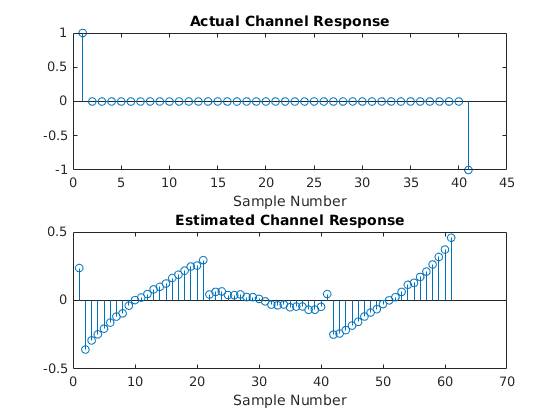

cf=getchannelcoeffs(x,y,61);

% add noise - when test case 2 is used
% noise = 0.351*randn(1,length(y));
% yn = y + noise;
% snr = 20*log10(std(yn)./std(noise));
% %% Test filter estimation
% cf=channel(x,yn,10);

%compare original and estimated channel
subplot(2,1,1)
stem(b)
title("Actual Channel Response")
xlabel("Sample Number")
subplot(2,1,2)

stem(cf)
title("Estimated Channel Response")
xlabel("Sample Number")